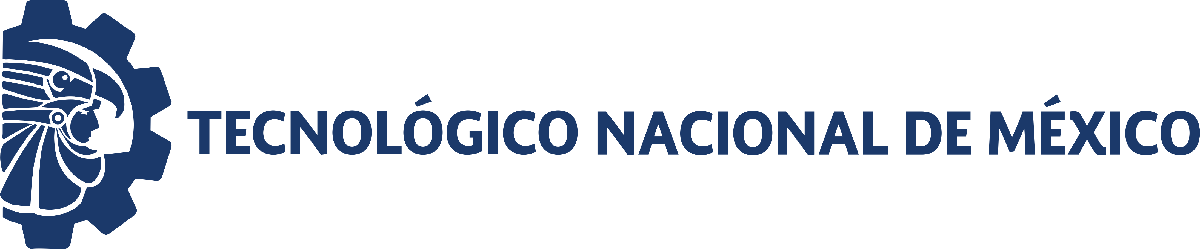                                 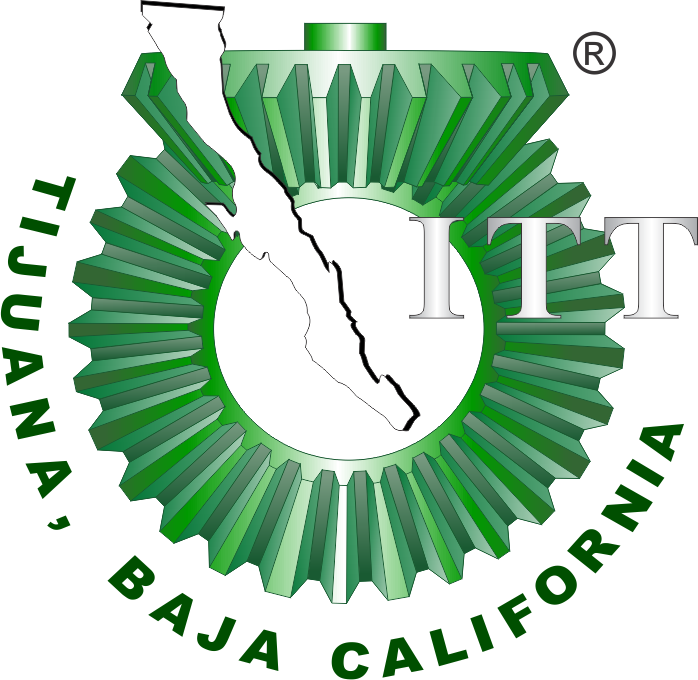

# Proyecto final : Sistema nervioso y sensorial en Neuropatía Diabética Periférica

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

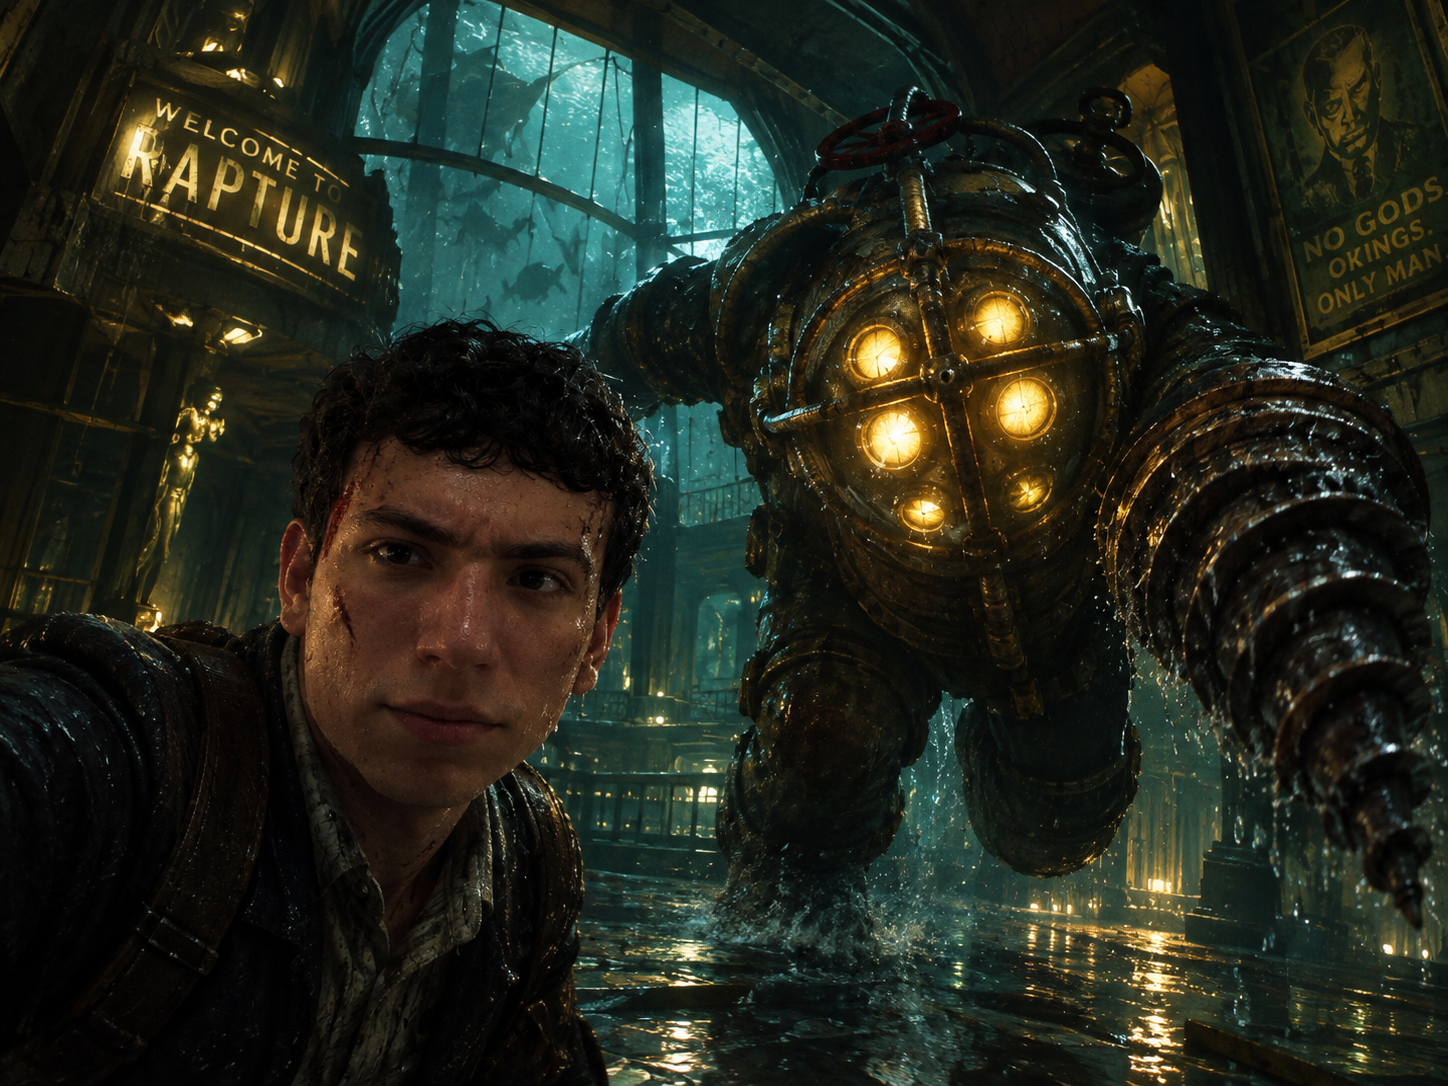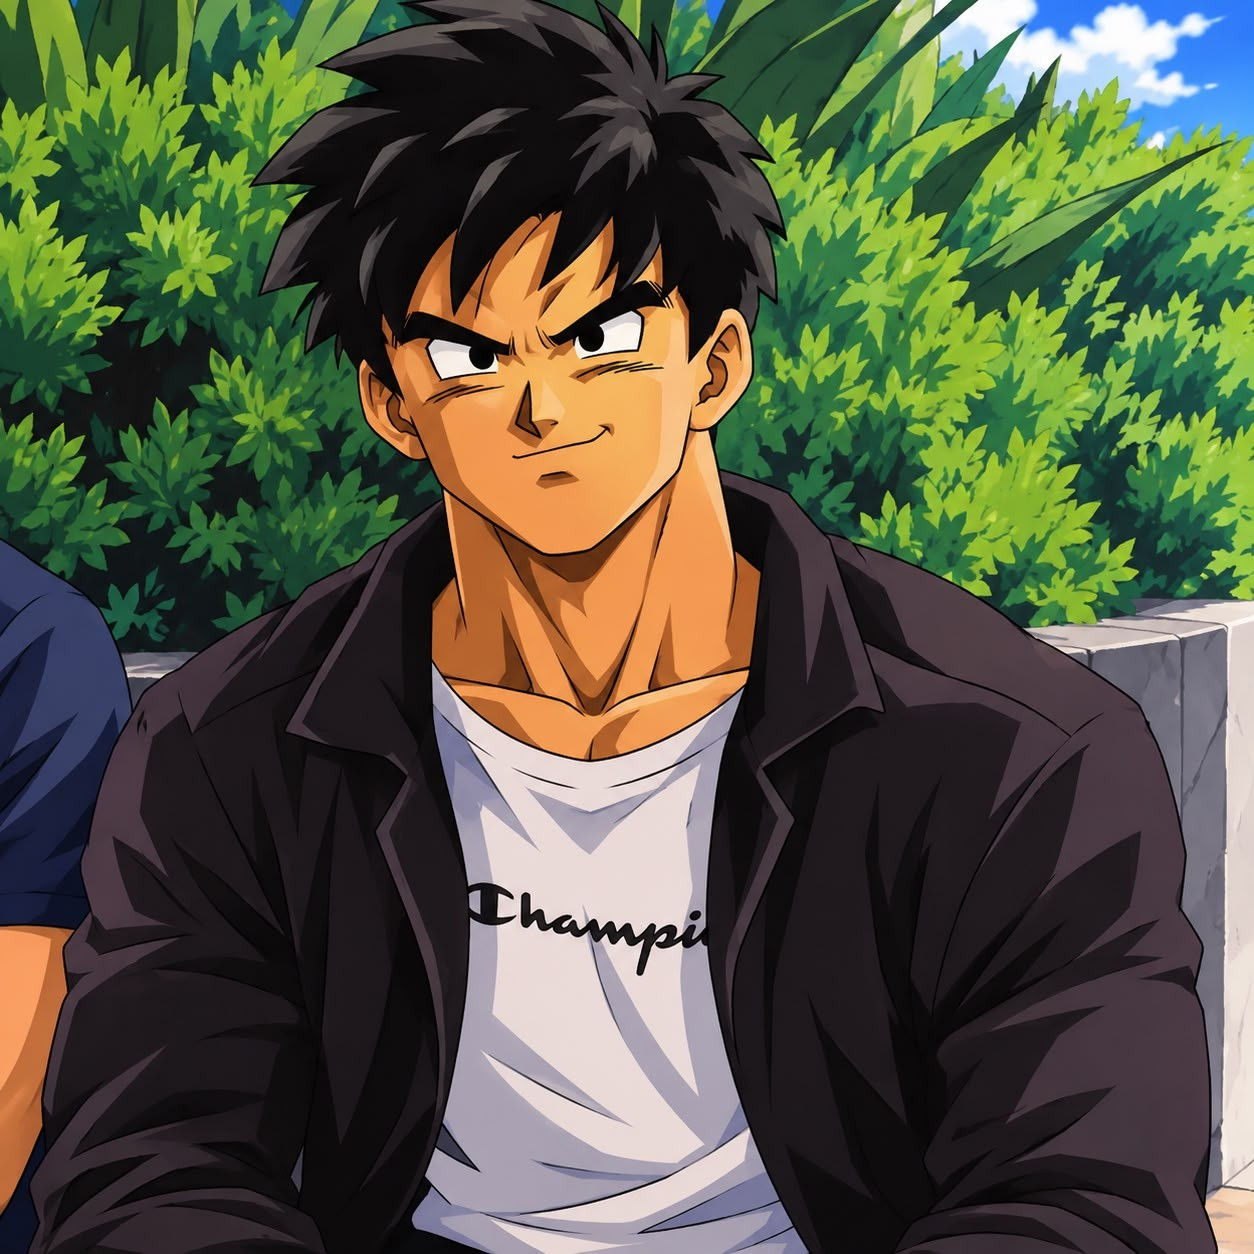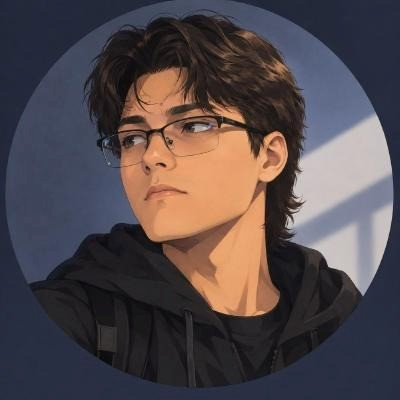

Inegrantes: 

Josue Raul Guerrero Peñaloza 24210583

Morales Diaz Ramon Ivan 24210589

Moreno Zavala Leonardo Zaid 24210590

Correos institucionales:

 l24210583**@tectijuana.edu.mx**

 l24210589**@tectijuana.edu.mx**

l24210590**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('sistema2020_5')
parameters.StopTime = '0.7';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-2';
x = sim('sistema2020_5',parameters);


## Respuesta Señales

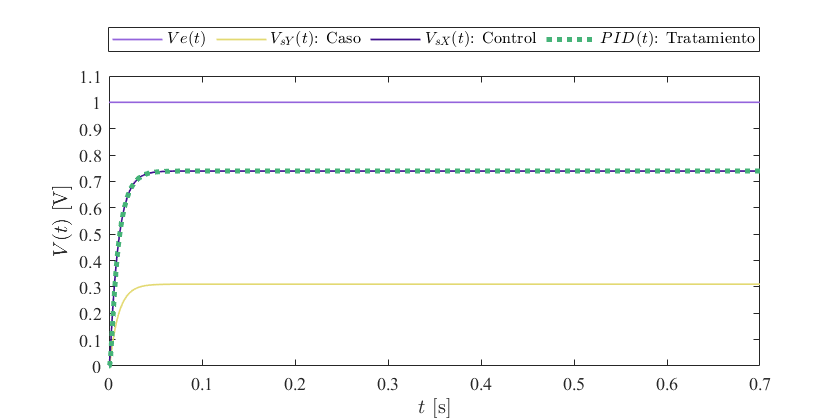

plotsignals(x.t, x.Ve, x.Vsy, x.Vsx, x.PID,'Caso')

## Funcion: Respuestas de la simulacion

function plotsignals (t,x1,x2,x3,x4,signal)
    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,7,3.5])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    clr1 = ([149, 100, 221])/256;
    clr2 = ([228, 218, 114])/256;
    clr3 = ([62, 15, 141])/256;
    clr4 = ([70, 180, 120]) / 256;
    order = [clr1; clr2; clr3; clr4]; colororder(order)
    xlabel('$t$ [s]','Interpreter','latex')
    ylabel('$V(t)$ [V]','Interpreter','latex')
    xlim([0 0.7]); xticks(0:0.1:0.7)

    if signal == "Caso"
        plot(t,x1,'-',t,x2,'-',t,x3,'-','LineWidth',1)
        plot(t,x4,':','LineWidth',3)
        L = legend('$Ve(t)$','$V_{sY}(t)$: Caso','$V_{sX}(t)$: Control','$PID(t)$: Tratamiento');
    end

    set(L,'interpreter','latex','location','northoutside','orientation','horizontal')
    ylim([0 1.1]); yticks(0:0.1:1.1)

    exportgraphics(gcf,[signal,'_matlab.pdf'],'ContentType','vector')
end